clc;clear;

main_dir = ['D:\Data\SimulationData_temp\tempdata' ...
    '\r_time0-time_horizon2-r_subject0-num_subjects8\'];
% main_dir = ['/storage08/shuchen/SimulationData/settingSSoS/' ...
%     'n500-k10-p_in2btw4-p_out1btw1/' ...
%     'r_time0-time_horizon2-r_subject0-num_subjects8/']
% main_dir = 'D:\OneDrive\OneDrive - UW-Madison\Sunduz\SimulationData\settingSSoT\n100-k2-p_in2btw25-p_out1btw1';
% main_dir = 'C:\OneDrive\OneDrive - UW-Madison\Sunduz\SimulationData\settingSSoT\n100-k2-p_in2btw25-p_out1btw1';

samplesTotal = 100;

% load data for the /0/ file
disp(main_dir);

D:\Data\SimulationData_temp\tempdata\r_time0-time_horizon2-r_subject0-num_subjects8\


sub_dir = dir(main_dir);
n_rep = 100;

i = 24;
i_rep = i-3;
path = [main_dir, sub_dir(i).name];
K_edges = 0:6:240;

ari_i = load([path,'/aris_ori.mat']).aris;
G = load([path,'/G_ori.mat']).G;
O = load([path,'/O_ori.mat']).O;
z = load([path,'/z_ori.mat']).zS;
size_z = size(z);
K_ori = zeros([size_z(1), size_z(2), size_z(4)]);

ari = mean(ari_i,[1,2]);
ari = reshape(ari, 100,1);


% find the number of communities (K) for each s,t, and sample
for s = 1:size_z(1)
    disp(s);
    for t = 1:size_z(2)
        for sample = 1:size_z(4)
            K_ori(s,t,sample) = max(unique(z(s,t,:,sample)));
        end
    end
end

     1

     2

     3

     4

     5

     6

     7

     8




% Average among subjects and time

K_st = mean(K_ori, [1,2]);  % K_st: mean of K among subjects and time
K_st = reshape(K_st, 100, 1);

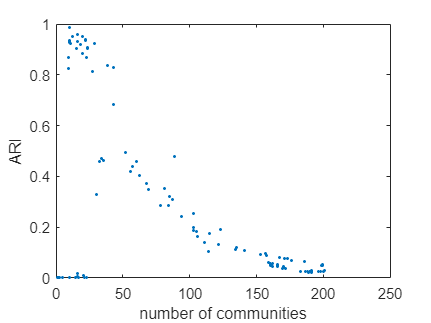

% nd = 4;
% nu = 4;
plot(K_st, ari, ".")
xlabel("number of communities")
ylabel("ARI")

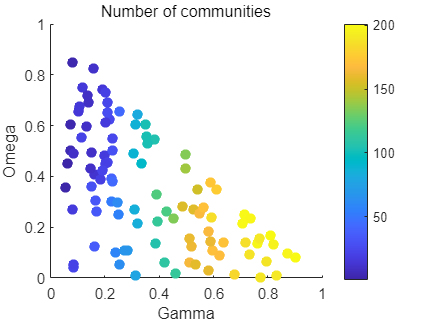

scatter(G,O, 50, K_st,"filled");
xlabel("Gamma")
ylabel("Omega")
title("Number of communities")
colorbar;

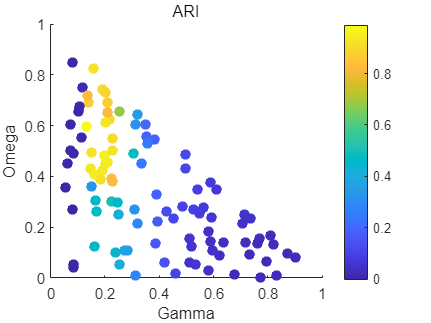

scatter(G,O, 50, ari,"filled");
xlabel("Gamma")
ylabel("Omega")
title("ARI")
colorbar;

% For the K closed to the ground truth
% ari = mean(ari_i,[1,2]);
% ari = reshape(ari, 100,1);
% ari_good = ari(K_mask);
% figure
% boxchart(ari_good)
% median(ari_good)
% histogram(ari_good,8)

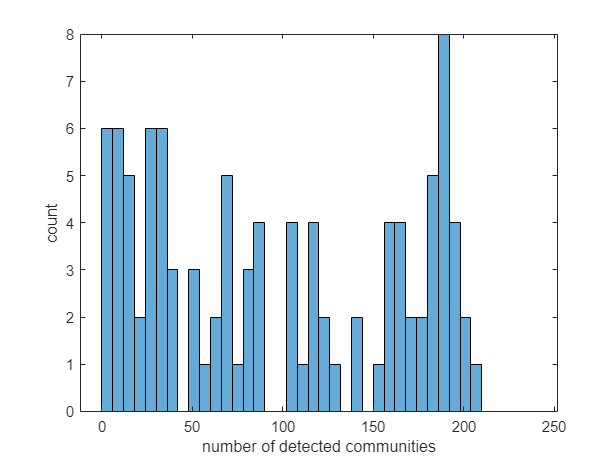

figure
h = histogram(K_st,K_edges);
xlabel("number of detected communities")
ylabel("count")

h.BinCounts

ans =      6     6     5     2     6     6     3     0     3     1     2     5     1     3     4     0     0     4     1     4     2     1     0     2     0     1     4     4     2     2     5     8     4     2     1     0     0     0     0     0


[counts,~] = histcounts(K_st, K_edges);
[~, i_freq] = max(counts);
K_mask = K_st>= K_edges(i_freq) & K_st<K_edges(i_freq+1);
ari_freq = ari(K_mask);

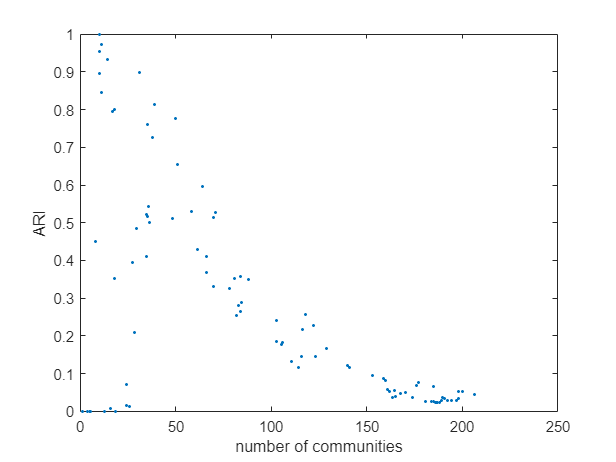

figure
boxchart(ari_freq)
median(ari_freq)

mask = K_st<10 & ari<0.2

mask = 100×1 logical 数组
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


z_freq = z(1,1,:,mask)

z_freq = z_freq(:,:,1,1) =

     1


z_freq(:,:,2,1) =

     1


z_freq(:,:,3,1) =

     1


z_freq(:,:,4,1) =

     1


z_freq(:,:,5,1) =

     1


z_freq(:,:,6,1) =

     1


z_freq(:,:,7,1) =

     1


z_freq(:,:,8,1) =

     1


z_freq(:,:,9,1) =

     1


z_freq(:,:,10,1) =

     1


z_freq(:,:,11,1) =

     1


z_freq(:,:,12,1) =

     1


z_freq(:,:,13,1) =

     1


z_freq(:,:,14,1) =

     1


z_freq(:,:,15,1) =

     1


z_freq(:,:,16,1) =

     1


z_freq(:,:,17,1) =

     2


z_freq(:,:,18,1) =

     1


z_freq(:,:,19,1) =

     1


z_freq(:,:,20,1) =

     1


z_freq(:,:,21,1) =

     1


z_freq(:,:,22,1) =

     1


z_freq(:,:,23,1) =

     1


z_freq(:,:,24,1) =

     1


z_freq(:,:,25,1) =

     1


z_freq(:,:,26,1) =

     1


z_freq(:,:,27,1) =

     1


z_freq(:,:,28,1) =

     1


z_freq(:,:,29,1) =

     1


z_freq(:,:,30,1) =

     1


z_freq(:,:,31,1) =

     1


z_freq(:,:,32,1) =

     1


z_freq(:,:,33,1) =

     1


z_freq(:,:,34,1) =

     1


z_freq(:,:,35,

z_freq = z_freq(1,1,:,1)

z_freq = z_freq(:,:,1) =

     1


z_freq(:,:,2) =

     1


z_freq(:,:,3) =

     1


z_freq(:,:,4) =

     1


z_freq(:,:,5) =

     1


z_freq(:,:,6) =

     1


z_freq(:,:,7) =

     1


z_freq(:,:,8) =

     1


z_freq(:,:,9) =

     1


z_freq(:,:,10) =

     1


z_freq(:,:,11) =

     1


z_freq(:,:,12) =

     1


z_freq(:,:,13) =

     1


z_freq(:,:,14) =

     1


z_freq(:,:,15) =

     1


z_freq(:,:,16) =

     1


z_freq(:,:,17) =

     2


z_freq(:,:,18) =

     1


z_freq(:,:,19) =

     1


z_freq(:,:,20) =

     1


z_freq(:,:,21) =

     1


z_freq(:,:,22) =

     1


z_freq(:,:,23) =

     1


z_freq(:,:,24) =

     1


z_freq(:,:,25) =

     1


z_freq(:,:,26) =

     1


z_freq(:,:,27) =

     1


z_freq(:,:,28) =

     1


z_freq(:,:,29) =

     1


z_freq(:,:,30) =

     1


z_freq(:,:,31) =

     1


z_freq(:,:,32) =

     1


z_freq(:,:,33) =

     1


z_freq(:,:,34) =

     1


z_freq(:,:,35) =

     1


z_freq(:,:,36) =

     1


z_freq(:,:,37) =

     1


z

% z_freq = reshape(z_freq, 18, 500)

disp(main_dir);

D:\Data\SimulationData_temp\tempdata\r_time0-time_horizon2-r_subject0-num_subjects8\


sub_dir = dir(main_dir);
n_rep = 100;
width = 8;
K_edges = 0:width:240;
aris_max = zeros([n_rep,1]);
aris_mean = zeros([n_rep,1]);
aris_med = zeros([n_rep,1]);
for i = 3:(n_rep+2)
    sub_dir = dir(main_dir);
    n_rep = 100;
    i_rep = i-3;
    disp(i_rep);
    path = [main_dir, sub_dir(i).name];
    
    ari_i = load([path,'/aris_ori.mat']).aris;
    z = load([path,'/z_ori.mat']).zS;
    size_z = size(z);
    K_ori = zeros([size_z(1), size_z(2), size_z(4)]);

%     ari_sample = mean(ari_i,[1,2]);
%     ari_sample = reshape(ari_sample, samplesTotal, 1);
%     aris_max(i_rep+1) = max(ari_sample);
%     aris_mean(i_rep+1) = mean(ari_sample); 
%     aris_med(i_rep+1) = median(ari_sample);
    
    % find the number of communities (K) for each s,t, and sample
    for s = 1:size_z(1)
        for t = 1:size_z(2)
            for sample = 1:size_z(4)
                K_ori(s,t,sample) = max(unique(z(s,t,:,sample)));
            end
        end
    end
    
    % Average among subjects and time
    K_st = mean(K_ori, [1,2]);  % K_st: mean of K among subjects and time
    K_st = reshape(K_st, 100, 1);
    [counts,~] = histcounts(K_st, K_edges);
    [~, i_freq] = max(counts);
%     disp(i_freq)
    K_mask = K_st>= K_edges(i_freq) & K_st<K_edges(i_freq+1);
    
    ari = mean(ari_i,[1,2]);
    ari = reshape(ari, 100,1);
    ari_freq = ari(K_mask);      
    aris_max(i_rep+1) = max(ari_freq);
    aris_mean(i_rep+1) = mean(ari_freq); 
    aris_med(i_rep+1) = median(ari_freq);
end

     0

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99



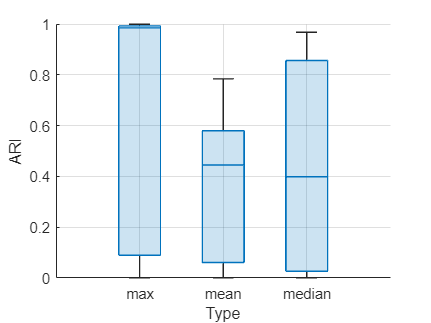


aris3 = [aris_max, aris_mean, aris_med];

figure
boxchart(aris3);         
hold on
grid on

xlabel("Type");
ylabel("ARI");
% title("width="+ width)
ylim([0,1]);
xticklabels(["max","mean","median"]);